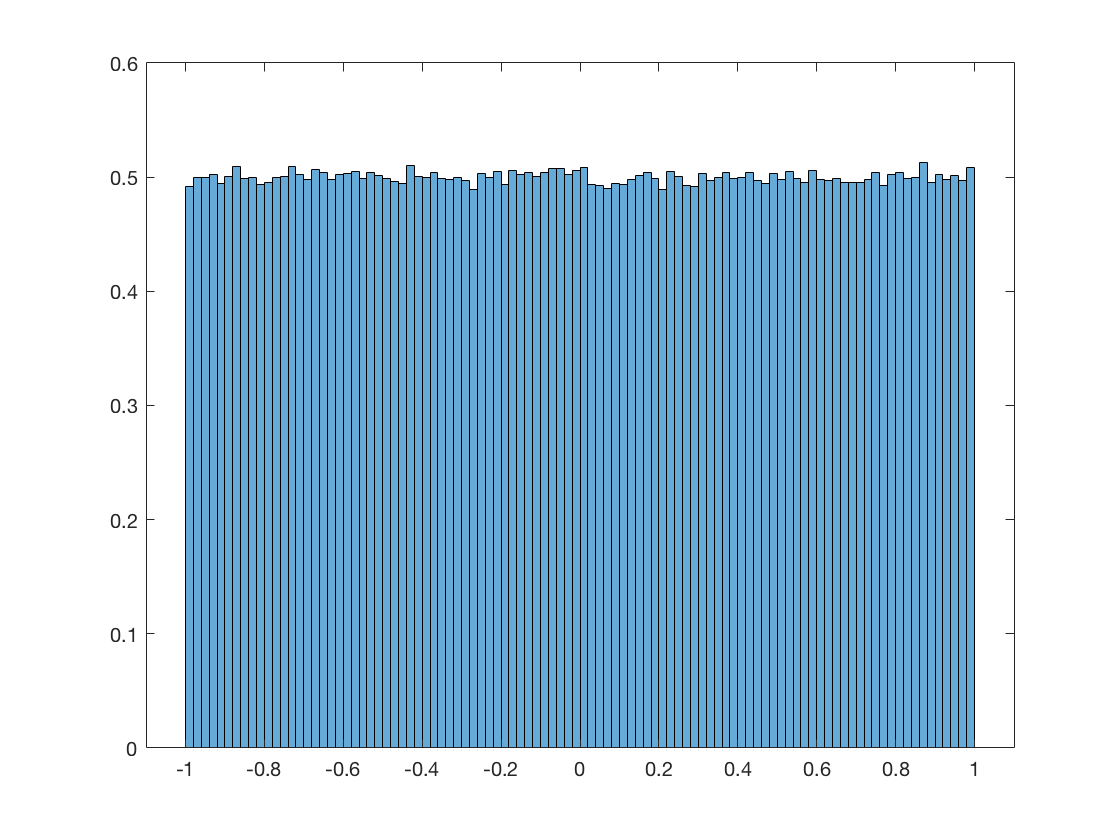

clear all
close all

fc = 8e3;
Tc = 1/fc;
B = 1/(2*Tc);

Npti=1e6;
nbit=6;
M=2^nbit;
V=1;
DeltaV=2*V/M;
pe=1e-5;

sig_in=2*rand(1,Npti)-1;

figure(1)
histogram(sig_in, 100, 'Normalization', 'pdf')

Quantizzazione

partition=[-V+DeltaV:DeltaV:V-DeltaV];
codebook=[-V+DeltaV/2:DeltaV:V-DeltaV/2];
[index,quants]=quantiz(sig_in,partition,codebook);

Decimale to Binario

word=de2bi(index, nbit);

Disturbo gaussiano sul canale

word_out=bsc(word,pe);

Ricevitore

index_out=bi2de(word_out);
sig_out=codebook(index_out+1);
err=sig_out-sig_in;

Spettro del segnale ricevuto

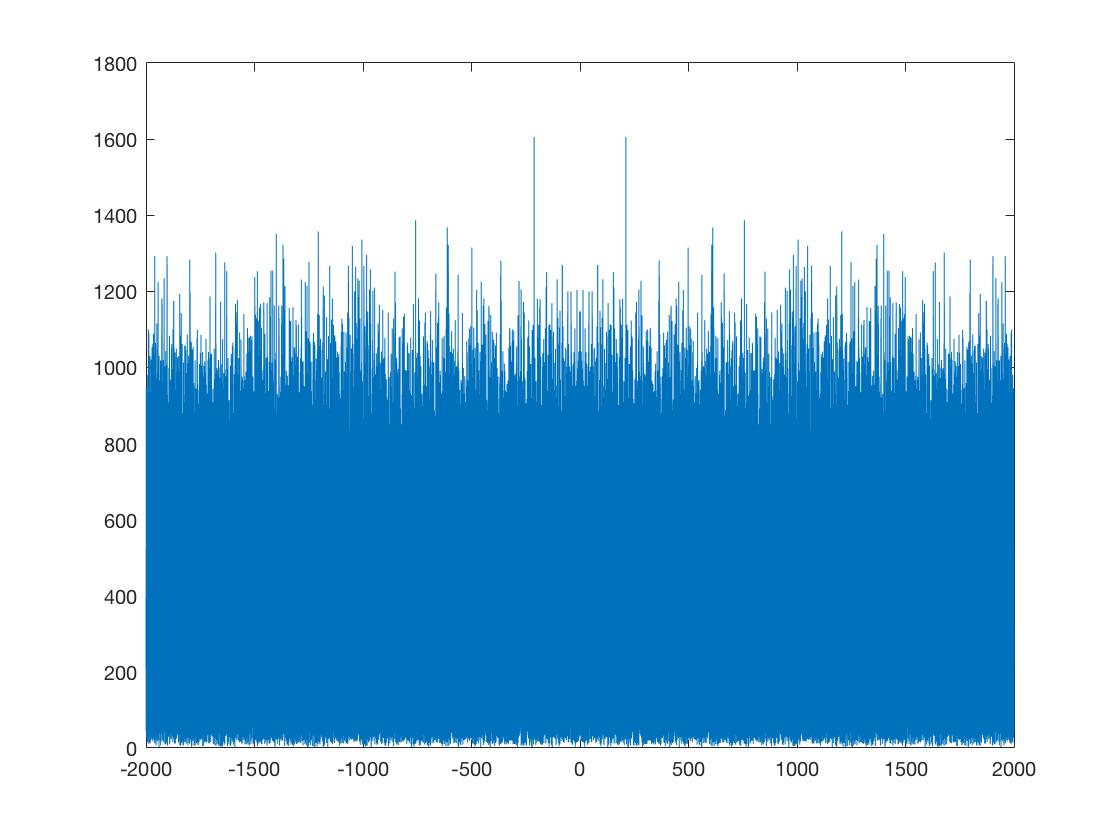

d_f = fc/length(sig_out);
f = (-B/2):d_f:(B/2-d_f);
F = abs(fft(sig_out, length(f))).^2;

figure(2)
plot(f, fftshift(F))

Valutazione del SNR rispetto a quello teorico

N=var(err);
S=var(sig_in);

reale = 10*log10(S/N)

reale = 35.6180


teorico = 10*log10(M^2)

teorico = 36.1236